# Тесты

## Тест 1

format long;
x_0 = 0;
x_n = 1;
t = sym('t');
q =@(t)(exp(-t/2).*log(t+3));
r =@(t)(1-(t+1).*exp(t));
f =@(t)(cos(t/2).*(t.^2+1));
alpha = [0.1 -0.1 -0.5];
beta = [0.4 1 0];
syms u(t);
Du = diff(u);

Решаем следующий дифур:

diff(u,2) + q*diff(u) - r*u == f

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}u\left(t\right)+\log\left(t+3\right)\,{\mathrm{e}}^{-\frac{t}{2}}\,\frac{\partial }{\partial t}u\left(t\right)+u\left(t\right)\,\left({\mathrm{e}}^{t}\,\left(t+1\right)-1\right)=\cos\left(\frac{t}{2}\right)\,\left(t^{2}+1\right)$$

Краевые условия:

alpha(1)*u(0)-alpha(2)*Du(0) == alpha(3)

$$ans = \frac{u\left(0\right)}{10}+\frac{{\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=0}}{10}=-\frac{1}{2}$$

beta(1)*u(1)+beta(2)*Du(1) == beta(3)

$$ans = \frac{2\,u\left(1\right)}{5}+\left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=1}\right)=0$$

Численное решение:

tic
epsilon = 1e-6;
[u_ch, x_ch, d] = Richardson(x_0, x_n, q, r, f, alpha, beta,epsilon);

Количество итераций:
     9



%h = (x_n-x_0)/10;   
toc

Elapsed time is 0.612106 seconds.


Погрешность:

d

d =      5.094523244005463e-07


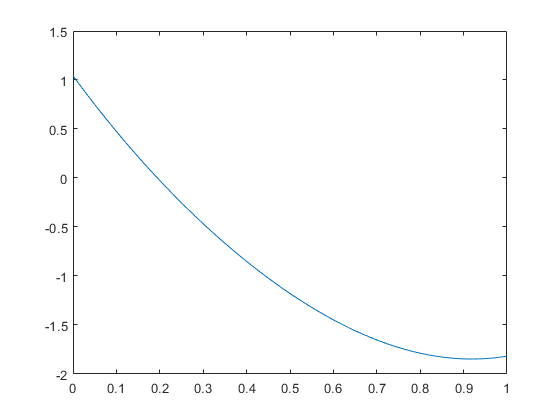

%[u_ch,x_ch] = net_met(x_0, h, x_n, q, r, f, alpha, beta);
plot(x_ch,u_ch);

## Тест 2

format long;
x_0 = 0;
x_n = 1;
t = sym('t');
q =@(t)(-cos(t)./(1+t));
r =@(t)((2-t));
f =@(t)(t+1);
alpha = [0.2 1 -0.2];
beta = [0.9 1 -0.1];
syms u(t);
Du = diff(u);

Решаем следующий дифур:

diff(u,2) + q*diff(u) - r*u == f

$$ans(t) = u\left(t\right)\,\left(t-2\right)-\frac{\cos\left(t\right)\,\frac{\partial }{\partial t}u\left(t\right)}{t+1}+\frac{\partial^{2}}{\partial t^{2}}u\left(t\right)=t+1$$

Краевые условия:

alpha(1)*u(0)-alpha(2)*Du(0) == alpha(3)

$$ans = \frac{u\left(0\right)}{5}-\left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=0}\right)=-\frac{1}{5}$$

beta(1)*u(1)+beta(2)*Du(1) == beta(3)

$$ans = \frac{9\,u\left(1\right)}{10}+\left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=1}\right)=-\frac{1}{10}$$

Численное решение:

tic
epsilon = 1e-6;
[u_ch, x_ch, d] = Richardson(x_0, x_n, q, r, f, alpha, beta,epsilon);

Количество итераций:
     7



%h = (x_n-x_0)/10;   
toc

Elapsed time is 0.083206 seconds.


Погрешность:

d

d =      7.052575999126157e-07


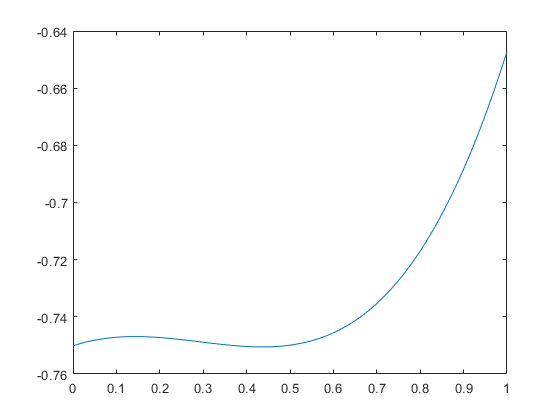

%[u_ch,x_ch] = net_met(x_0, h, x_n, q, r, f, alpha, beta);
plot(x_ch,u_ch);

## Тест 3

format long;
x_0 = -1;
x_n = 1;
t = sym('t');
q =@(t)(-(t-3).*(1+t));
r =@(t)((t-3).*exp(t));
f =@(t)((t-3).*(t-2));
alpha = [1 0 0];
beta = [1 0 0];
syms u(t);
Du = diff(u);

Решаем следующий дифур:

diff(u,2) + q*diff(u) - r*u == f

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}u\left(t\right)-\left(t+1\right)\,\left(t-3\right)\,\frac{\partial }{\partial t}u\left(t\right)-{\mathrm{e}}^{t}\,u\left(t\right)\,\left(t-3\right)=\left(t-2\right)\,\left(t-3\right)$$

Краевые условия:

alpha(1)*u(-1)-alpha(2)*Du(-1) == alpha(3)

$$ans = u\left(-1\right)=0$$

beta(1)*u(1)+beta(2)*Du(1) == beta(3)

$$ans = u\left(1\right)=0$$

Численное решение:

tic
epsilon = 1e-6;
[u_ch, x_ch, d] = Richardson(x_0, x_n, q, r, f, alpha, beta,epsilon);

Количество итераций:
    11



%h = (x_n-x_0)/10;   
toc

Elapsed time is 23.295862 seconds.


Погрешность:

d

d =      4.999758663378392e-07


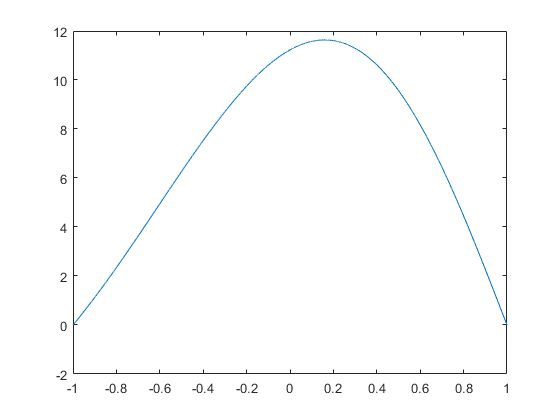

%[u_ch,x_ch] = net_met(x_0, h, x_n, q, r, f, alpha, beta);
plot(x_ch,u_ch);

## Тест 4

format long;
x_0 = 0;
x_n = pi/2;
t = sym('t');
q =@(t)(t.*sin(t)+t.^2);
r =@(t)(-t.*sin(t)+cos(t));
f =@(t)((t.^3-t.^2).*cos(t));
alpha = [1 0 0.5];
beta = [0 -1 0 ];
syms u(t);
Du = diff(u);

Решаем следующий дифур:

diff(u,2) + q*diff(u) - r*u == f

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}u\left(t\right)+\left(t\,\sin\left(t\right)+t^{2}\right)\,\frac{\partial }{\partial t}u\left(t\right)-u\left(t\right)\,\left(\cos\left(t\right)-t\,\sin\left(t\right)\right)=-\cos\left(t\right)\,\left(t^{2}-t^{3}\right)$$

Краевые условия:

alpha(1)*u(0)-alpha(2)*Du(0) == alpha(3)

$$ans = u\left(0\right)=\frac{1}{2}$$

beta(1)*u(pi/2)+beta(2)*Du(pi/2) == beta(3)

$$ans = -\left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=\frac{\pi }{2}}\right)=0$$

Численное решение:

tic
epsilon = 1e-6;
[u_ch, x_ch, d] = Richardson(x_0, x_n, q, r, f, alpha, beta,epsilon);

Количество итераций:
    10



%h = (x_n - x_0)/10;
toc

Elapsed time is 8.401617 seconds.


Погрешность:

d

d =      3.787199147620157e-07


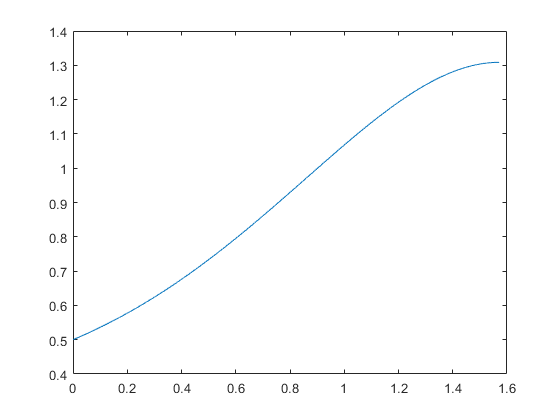

%[u_ch,x_ch] = net_met(x_0, h, x_n, q, r, f, alpha, beta);
plot(x_ch,u_ch);

## Тест 5

format long;
x_0 = -1;
x_n = 1;
t = sym('t');
q =@(t)((1-t/2).*(7+3*t)./(6+t));
r =@(t)((1+cos(t)/2).*(7+3*t)./(6+t));
f =@(t)(-(1-t/3).*(7+3*t)./(6+t));
alpha = [-2 -1 0];
beta = [0 1 0];
syms u(t);
Du = diff(u);

Решаем следующий дифур:

diff(u,2) + q*diff(u) - r*u == f

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}u\left(t\right)-\frac{u\left(t\right)\,\left(3\,t+7\right)\,\left(\frac{\cos\left(t\right)}{2}+1\right)}{t+6}-\frac{\left(\frac{t}{2}-1\right)\,\left(3\,t+7\right)\,\frac{\partial }{\partial t}u\left(t\right)}{t+6}=\frac{\left(\frac{t}{3}-1\right)\,\left(3\,t+7\right)}{t+6}$$

Краевые условия:

alpha(1)*u(-1)-alpha(2)*Du(-1) == alpha(3)

$$ans = \left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=-1}\right)-2\,u\left(-1\right)=0$$

beta(1)*u(1)+beta(2)*Du(1) == beta(3)

$$ans = \left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=1}\right)=0$$

Точное решение:

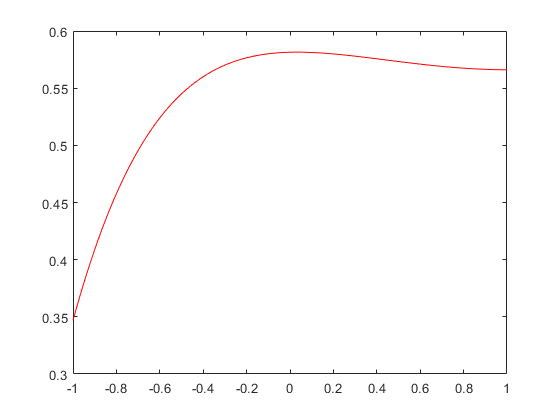

tic
fun = @(x,y) [y(2); ...
    -(1-x/2)*(7+3*x)/(6 + x)*y(2)+((1 + cos(x)/2)*(7+3*x)/(6 + x))*y(1)-(1-x/3)*(7+3*x)/(6 + x)];
bc = @(ya, yb) [-2*ya(1)+ya(2); yb(2)];
xmesh = linspace(-1, 1, 1000);
solinit = bvpinit(xmesh, [0 1]);
sol = bvp4c(fun, bc, solinit);
plot(sol.x,sol.y(1,:),'r');

toc

Elapsed time is 4.591756 seconds.


Численное решение:

tic
epsilon = 1e-6;
[u_ch, x_ch, d] = Richardson(x_0, x_n, q, r, f, alpha, beta,epsilon);

Количество итераций:
     8



%h = (x_n - x_0)/10;
toc

Elapsed time is 0.321597 seconds.


Погрешность:

d

d =      4.150545392563506e-07


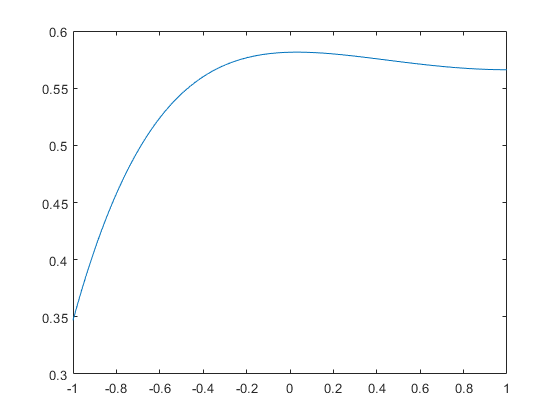

%[u_ch,x_ch] = net_met(x_0, h, x_n, q, r, f, alpha, beta);
plot(x_ch,u_ch);